clc; clear; close all;
data = readtable('arm_workspace_points.csv');
inputs = [data.theta1_deg, data.theta2_deg, data.theta3_deg, data.q4_mm]';
targets = [data.x_mm, data.y_mm, data.z_mm]';
size(inputs)

ans =            4       50000


size(targets)

ans =            3       50000


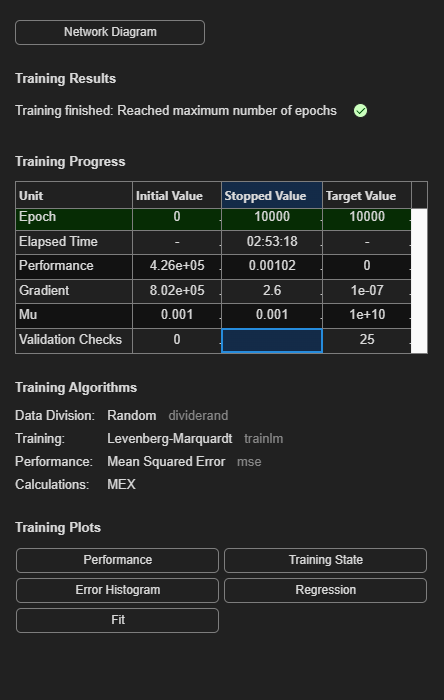

net = fitnet([20 10], 'trainlm');

net.divideFcn = 'dividerand';
net.divideParam.trainRatio = 0.70;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

net.performFcn = 'mse';
net.trainParam.epochs = 10000;
net.trainParam.max_fail = 25;

[net,tr] = train(net,inputs,targets);


predicted = net(inputs);
testInd = tr.testInd;
actualTest = targets(:,testInd);
predictedTest = predicted(:,testInd);

error = actualTest - predictedTest;
RMSE = sqrt(mean(error.^2,2));
MAE = mean(abs(error),2);
R2 = 1 - sum(error.^2,2) ./ sum((actualTest-mean(actualTest,2)).^2,2);

fprintf('X RMSE = %.4f mm\n',RMSE(1));

X RMSE = 0.0298 mm


fprintf('Y RMSE = %.4f mm\n',RMSE(2));

Y RMSE = 0.0338 mm


fprintf('Z RMSE = %.4f mm\n',RMSE(3));

Z RMSE = 0.0310 mm


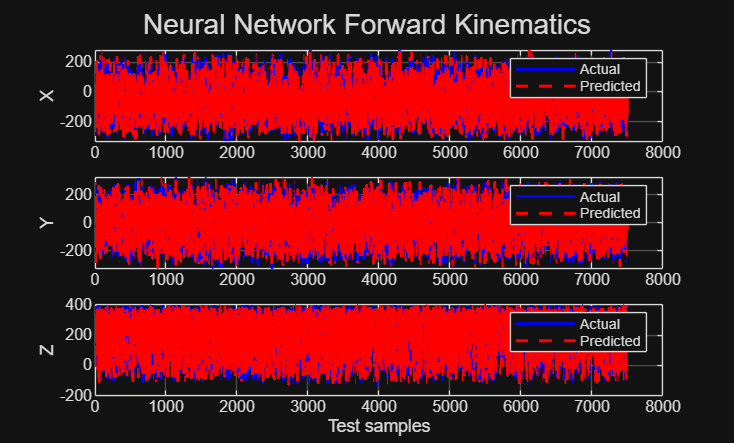

figure;
names = {'X','Y','Z'};
for i = 1:3
subplot(3,1,i);
plot(actualTest(i,:),'b','LineWidth',1.5);
hold on;
plot(predictedTest(i,:),'r--','LineWidth',1.5);
ylabel(names{i});
legend('Actual','Predicted');
grid on;
end
xlabel('Test samples');
sgtitle('Neural Network Forward Kinematics');

newAngles = [30; 145; 160; 180];
newPosition = net(newAngles);
fprintf('\nPredicted Position:\n');


Predicted Position:


fprintf('X = %.4f mm\n',newPosition(1));

X = 151.6129 mm


fprintf('Y = %.4f mm\n',newPosition(2));

Y = -262.7536 mm


fprintf('Z = %.4f mm\n',newPosition(3));

Z = 334.2848 mm


save('Forward_Kinematics_Model.mat','net','tr');